## Preproccessing file 

### In this file we loop through all CNT data of our EEG data set. It then is..

.. Downsampled

.. High-pass filtered

.. Low-pass filtered

.. Zapline filtered (to be added)

% Load eeglab
eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\rosah\eeg_options.m


Retrieving plugin versions from server...
Retreiving download statistics...


EEGLAB: adding "ANTeepimport" v1.13 (see >> help eegplugin_eepimport)


EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel)


EEGLAB: adding "clean_rawdata" v2.2 (see >> help eegplugin_clean_rawdata)


EEGLAB: adding "dipfit" v3.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "fieldtrip-" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)
EEGLAB: adding "libeep-" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "neuroscanio-master" v1.3 (see >> help eegplugin_neuroscanio)


You are using the latest version of EEGLAB.


% Enter your path do the data
saving_path = 'C:\Users\rosah\Desktop\Rosas Unikrams\6th semester from Asus\Parkinson study project\Thesis things\EEG_feelSpace\EEG_data_feelSpace\CNT_DownsampledAndFiltered'

saving_path = 'C:\Users\rosah\Desktop\Rosas Unikrams\6th semester from Asus\Parkinson study project\Thesis things\EEG_feelSpace\EEG_data_feelSpace\CNT_DownsampledAndFiltered'

data_path = 'C:\Users\rosah\Desktop\Rosas Unikrams\6th semester from Asus\Parkinson study project\Thesis things\EEG_feelSpace\EEG_data_feelSpace\'

data_path = 'C:\Users\rosah\Desktop\Rosas Unikrams\6th semester from Asus\Parkinson study project\Thesis things\EEG_feelSpace\EEG_data_feelSpace\'

cd(data_path)

Date: 29-10-2020 


file to load: EEG_feelSpace_participant15.cnt 


r = struct with fields:
    v4_info: [1×1 struct]
    sample1: 1
    sample2: 3565090
    v4_data: [1×1 struct]


eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


resampling data 256.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 
resampling event latencies...
resampling finished


pop_eegfiltnew() - performing 8449 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): 0.1 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.05 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_eegfiltnew() - performing 35 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 100 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 112.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Saving dataset...


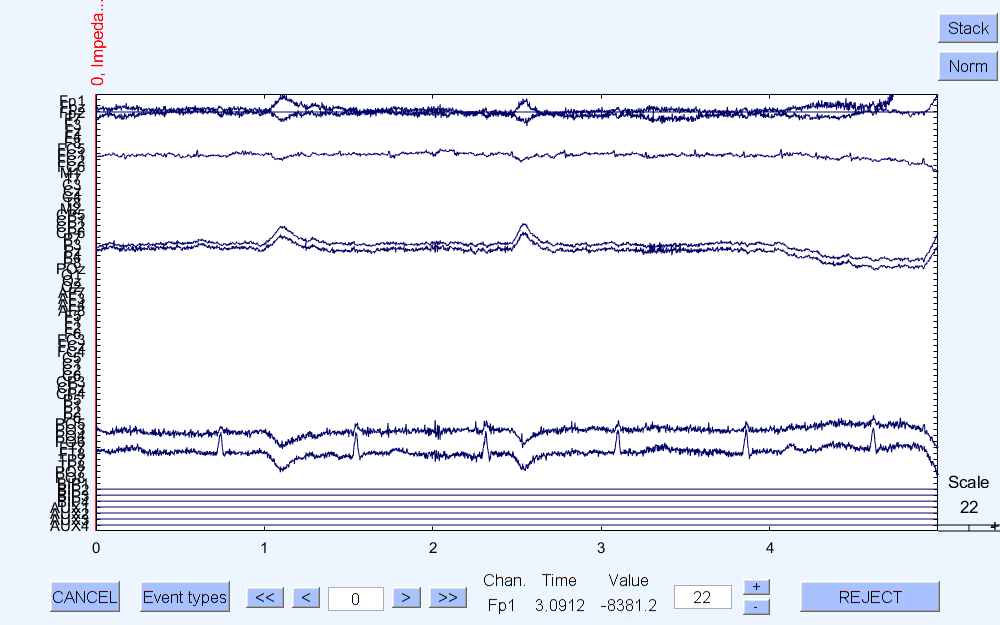

r = struct with fields:
    v4_info: [1×1 struct]
    sample1: 1
    sample2: 3565090
    v4_data: [1×1 struct]


eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



% Load all the CNT file we have and downsample and filter them
all_dates = dir();

% Iterator i defines over how many folders you would like to iterate
for i = 18:18
    fprintf("Date: %s \n", all_dates(i).name);
    cd(all_dates(i).name);

    % Extract the .cnt file out of the data foulders
    all_files = dir();
    all_files = struct2cell(all_files);
    all_files_names = all_files(1, :);
    unique_bools = contains(all_files_names, 'cnt');
    unique_subjects = all_files_names(unique_bools);
    nr_subj = length(unique_subjects);
    
    for j = 1:nr_subj-1
        file = unique_subjects{j};
        fprintf("file to load: %s \n", file);

        % load file
        eeg_cnt = pop_loadeep_v4(file);
        eeg_cnt.preprocessing = [];
        
        % DOWNSAMPLING
        eeg_cnt = pop_resample(eeg_cnt, 256);
        eeg_cnt.preprocessing = [eeg_cnt.preprocessing 'Downsampling, '];
        
        % HIGH- AND LOW-PASS FILTERING
        eeg_cnt = pop_eegfiltnew(eeg_cnt, 0.1, []); % 0.1 is the lower edge 
        eeg_cnt.preprocessing = [eeg_cnt.preprocessing 'Highpass, '];
        
        eeg_cnt = pop_eegfiltnew(eeg_cnt, [], 100); % 100 is the upper edge 
        eeg_cnt.preprocessing = [eeg_cnt.preprocessing 'Lowpass, '];
        
        % DEBLANKING (only has to be used here in our NBP EEG lab)
        x=size(eeg_cnt.event);
        for t=1:max(x)
            eeg_cnt.event(t).type = deblank(eeg_cnt.event(t).type);
        end
        
        eeg_cnt.preprocessing = [eeg_cnt.preprocessing 'Deblanked,'];

        
        % SAVING DATA
        eeg_cnt = pop_editset(eeg_cnt, 'setname', eeg_cnt);
        ID = extract(file, digitsPattern);
        new_filename = ['ID' ID{1}];
        eeg_cnt = pop_saveset(eeg_cnt, 'filename', new_filename, 'filepath', saving_path);
        
    end
    cd ..\
end